# **wavelet-RnB Live, version 02**

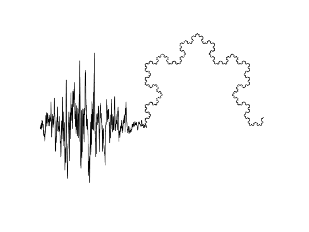

## *wavelet-RnB*

#### *(J.M. Lina, M-C. Foti, 2024)*

#### The w-*RnB* is a wavelet-based processing aiming at disantangling the rhythmic and arrhythmic components of electrophysiological signals. This Live Script reproduces the Fig.4 of the main reference. It allows to experiment the wRnB on other data with a prescribed format as indicated below. 

#### The main reference: J. Dubé et al., *Rhythms and Background (RnB): the spectroscopy of sleep recordings*, 2024

- **1 - Initialization and data selection **

 
clc; clear; close all;
restoredefaultpath;
% librairy RnB
addpath(genpath('./RnB_v01'), 'data','ressources');
make_introd();


    This demo applies the wavelet-RnB algorithm to produce the
    spectrum of scaling exponents and the 'rhythmic spectral
    annalysis from a collection of epochs.
    The multiresolution analysis is obtained from an orthonormal 
    discrete wavelet basis in the fractional spline family (T.Blu
    and M.Unser, 1993)
    The 'sleep data' are samples from the MNI-open iEEG atlas
    (N. Ellenrieder et al., 2020)


- **You can choose a region (or your own data): **

close all
region = 6;

   dbs = dir('./data/R*');
   if region~=8
   load([dbs(region).folder filesep dbs(region).name])
   make_status(region,data_epochs,fs);
   elseif region == 8
       [data_epochs,fs] = make_status6('./data/');
   end


    You selected Hippocampus (NREM3):
	 . 1688 epochs
	 . 2048 samples (10.24 seconds @ 200.00 Hz)
	 . The wRnB will take max. 9.4 minutes.
	 . To proceed, press the next button 'wavelet-RnB' ... and be patient ...

- **2 - Apply w-*****RnB***

Elapsed time is 271.727664 seconds.


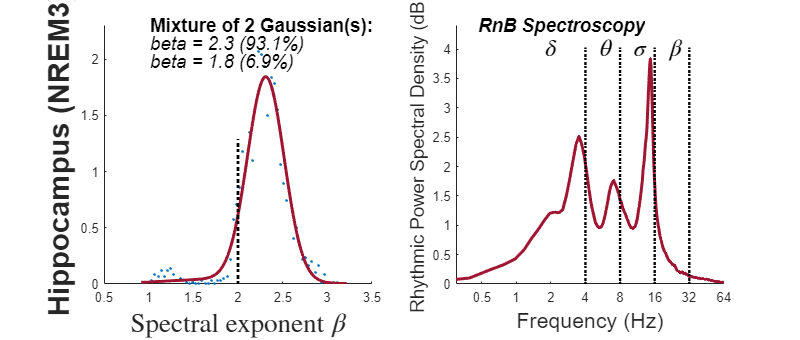


    Bases on 1688 epochs, the left figure displays the distribution of the
    scaling exponent across the epochs. The curve is an optimal fit (in
    terms of an optimal Akaike Index Criteria) with a mixture of Gaussians.
    The right figure shows the 'RnB spectroscopy' of the Hippocampus (NREM3)


 
if ~isempty(data_epochs)
tic
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%                         
[sR, pW] = wRnB_extract_Rhythmic_signals(data_epochs,'alpha', 4,'J', 8,'verbose',0);%
pR = RnB_compute_spectre_brut(sR,fs);                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
toc
% Display 
make_figure(pR,pW,sR,region);
else
    fprintf('\n   No data availlable.');
end

 
if exist('sR','var')
    fprintf(' -- You save in ''RnB_results.mat'' the following results\n');
    fprintf('\t . The rhythmic signals (sR : epochs x time)\n');
    fprintf('\t . The beta exponents (betas : epochs x 1)\n');
    fprintf('\t . The specific region (region : string)\n');
    betas = pW.betas;
    save('wRnB_results.mat','betas','sR','region');
end

 -- You save in 'RnB_results.mat' the following results


	 . The rhythmic signals (sR : epochs x time)


	 . The beta exponents (betas : epochs x 1)


	 . The specific region (region : string)


fprintf('\n   Bye.\n');


   Bye.
